# 案例：用 Matlab 绘制高质量的论文插图 3

## 自定义颜色图

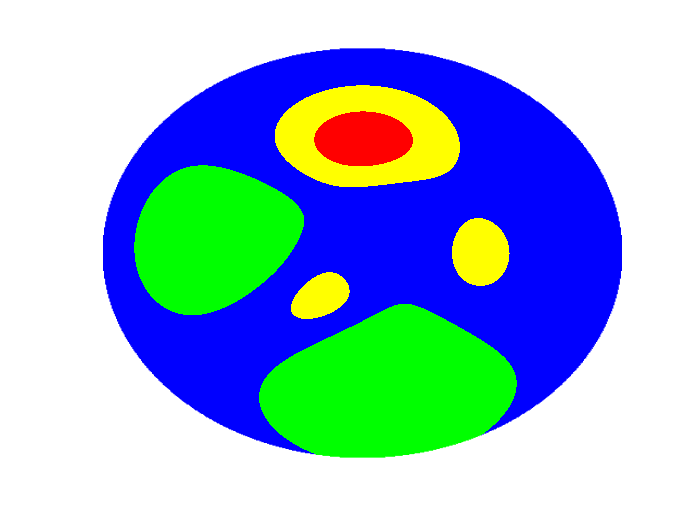

clear;clc;
N = 500;
z = peaks(N);
% 选择 ROI 以外的不显示
for i = 1:N
    for j = 1:N
        if sqrt((i - N/2)*(i - N/2) + (j - N/2)*(j - N/2)) > 240
            z(i, j) = nan;
        end
    end
end
% 自定义颜色 大概就是给特定范围值指定颜色
N = 14 * 5;
crange = linspace(-6, 8, N);
cmap = zeros(N, 3);
for i = 1:N
    if crange(i) <= 0
        cmap(i, :) = [0, 1, 0];
    elseif crange(i) <= 3
        cmap(i, :) = [0, 0, 1];
    elseif crange(i) <= 6
        cmap(i, :) = [1, 1, 0];
    else
        cmap(i, :) = [1, 0, 0];
    end
end
figure;
surf(z)
colormap(cmap);
% 去网格
shading interp
% 视角
view(0, 90);
% 去坐标轴
axis off

## gif 动态图

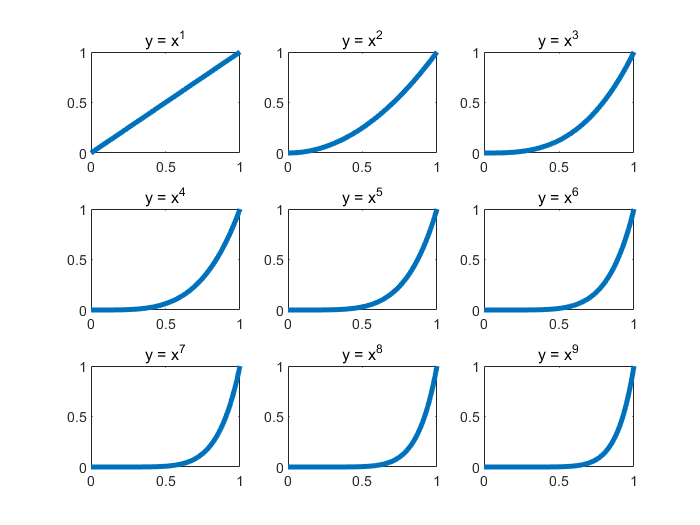

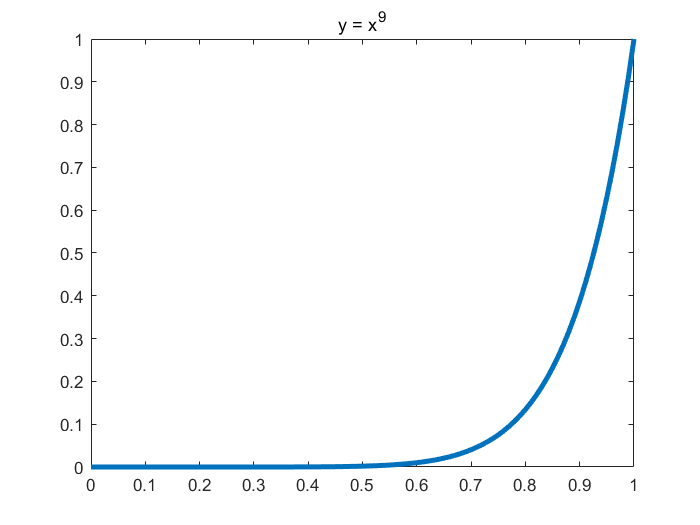

clear; clc;
x = 0:0.01:1;
n = 1:9;
len = length(n);
im = cell(1, len);
% 单独显示每个图
figure;
for idx = 1:len
    subplot(3, 3, idx)
    plot(x, x.^idx, 'LineWidth',3)
    title(['y = x^', num2str(idx)])
end
% 获取绘制对象
fig = figure(1);
for idx = 1:len
    y = x.^idx;
    plot(x, y, 'LineWidth', 3)
    title(['y = x^', num2str(n(idx))])
%     drawnow
%     pause(0.1);
    frame = getframe(fig);
    im{idx} = frame2im(frame);
end

% 输出文件名
% filename = 'testAnimated.gif'; 
% for idx = 1:len
%     % 制作gif文件，图像必须是index索引图像
%     [A, map] = rgb2ind(im{idx}, 256);
%     if idx == 1
%         imwrite(A, map, filename, 'gif', 'LoopCount', Inf, 'DelayTime', 0.3);
%     else
%         imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.3);
%     end
% end

## 方程曲线图

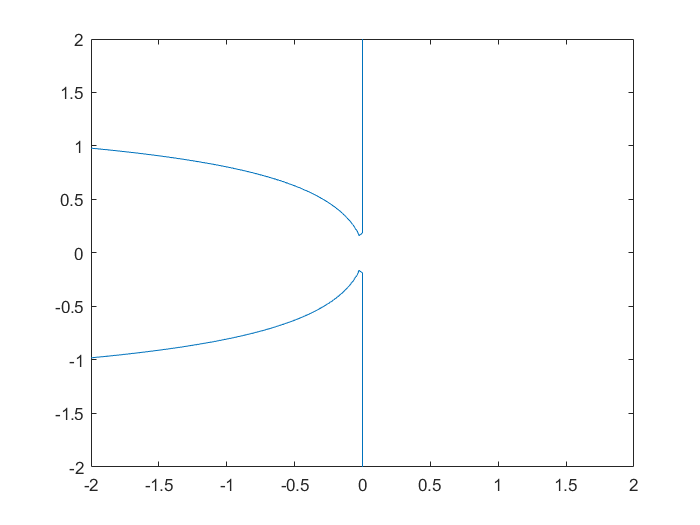

% 二元方程  x^2*cos(y) + x*sinh(y^2) = 0
xy = linspace(-2, 2, 4);
[x, y] = meshgrid(xy);
f = @(x, y) x.^2.*cos(y) + x.*sinh(y.^2);
figure
fimplicit(f, [-2, 2]);

## 极坐标图

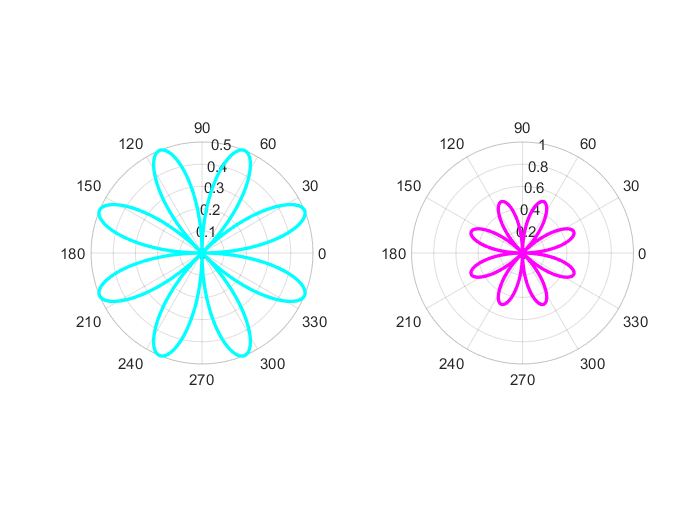

figure;
theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(2*theta);
tiledlayout(1, 2);
nexttile;
polarplot(theta, rho, 'c', 'LineWidth', 2);
nexttile;
rMax = 2*max(rho);
% 这个看不到线，因为只有一个重复的点
polarplot([0, 2*pi], [rMax, rMax]);    
hold on
polarplot(theta, rho, 'm', 'LineWidth', 2);
hold off

## 不相交随机圆

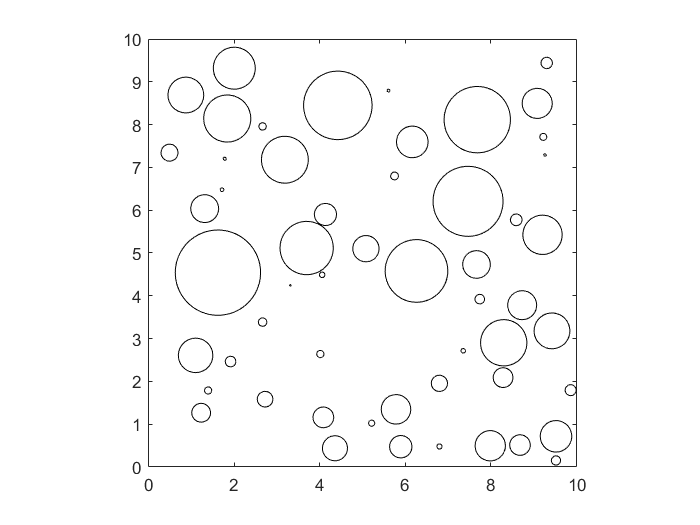

clear;clc;close all;
% 限定范围
width = 10;  
height = 10;
% 最多产生的圆的个数
circleNumber = 100;   
% 记录每个圆的横坐标、纵坐标、半径
paras = zeros(circleNumber, 3);  
num = 0;
hold on
while num < circleNumber
    num = num + 1;    
    % 圆半径小于1或者设定为固定值
    r = rand; 
    % 在范围内随机坐标
    xPos = rand*(width-2*r) + r;  
    yPos = rand*(height-2*r) + r;
    % 记录坐标、半径
    paras(num,:) = [xPos, yPos, r];
    % 判断每个圆的位置是否不相切、不相交
    if num > 1
        % 新产生的圆和之前产生的所有圆计算距离        
        xs = paras(1:num - 1, 1);
        ys = paras(1:num - 1, 2);
        rs = paras(1:num - 1, 3);
        dist1 = sqrt((xPos - xs).^2 + (yPos - ys).^2);
        dist2 = abs(r + rs);
        % 如果相离则绘制当前产生的圆，否则就重新生成一个圆
        if all(dist1 > dist2)
            rectangle('Position', [xPos-r, yPos-r, 2*r, 2*r], 'Curvature', [1 1]);
            axis equal
        else
            r = rand; 
            xPos = rand*(width-2*r) + r;  
            yPos = rand*(height-2*r) + r;
            paras(num,:) = [xPos,yPos,r];
            % 防止死循环
            temp = 0;
            maxTry = 100;
            while any(dist1 <= dist2) && temp < maxTry
                temp = temp + 1;
                dist1 = sqrt((xPos - xs).^2 + (yPos - ys).^2);
                dist2 = abs(r + rs);
            end
            if all(dist1 > dist2)
                rectangle('Position', [xPos-r, yPos-r, 2*r, 2*r], 'Curvature', [1 1]);
                axis equal
            end
        end      
    end
end
axis([0 width 0 height])
box on
hold off

## BP 神经网络图

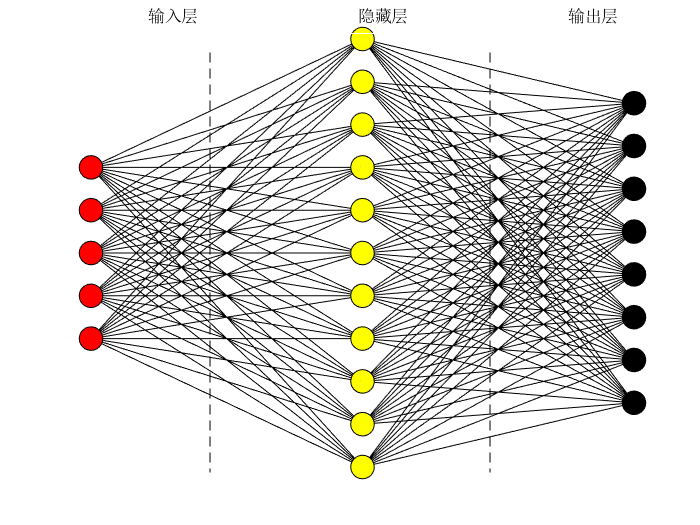

figure;
x1 = ones(1, 5);
x2 = 2 * ones(1, 11);
x3 = 3 * ones(1, 8);
y1 = 4:8;
y2 = 1:11;
y3 = 2.5:9.5;
for i = 1:5
    for j = 1:11
        plot([x1(i), x2(j)], [y1(i), y2(j)], 'k');
        hold on
    end
end
for i = 1:11
    for j = 1:8
        plot([x2(i), x3(j)], [y2(i), y3(j)], 'k');
    end
end
scatter(x1, y1, 200, 'k', 'MarkerFaceColor', 'r');
scatter(x2, y2, 200, 'k', 'MarkerFaceColor', 'y');
scatter(x3, y3, 200, 'k', 'MarkerFaceColor', 'k');
hold off
axis off
annotation('line', [0.3 0.3], [0.9 0.1], 'LineStyle','--');
annotation('line', [0.7 0.7], [0.9 0.1], 'LineStyle','--');
% 创建 textbox
annotation('textbox', [0.2 0.9 0.2 0.1], 'String', '输入层', 'FitBoxToText', 'on', 'EdgeColor', 'w');
annotation('textbox', [0.5 0.9 0.2 0.1], 'String', '隐藏层', 'FitBoxToText', 'on', 'EdgeColor', 'w');
annotation('textbox', [0.8 0.9 0.2 0.1], 'String', '输出层', 'FitBoxToText', 'on', 'EdgeColor', 'w');